% Problem 0
load('Homework4.mat')

% Problem 1

modelfunc = @(x,h) sum(x*h,2);

% define
n = size(data1,1)

n = 1000

numboots = 500;   % number of bootstraps to perform
size_of_regressors = size(regressors1,2)

size_of_regressors = 100

bunch_of_sample = 500

bunch_of_sample = 500

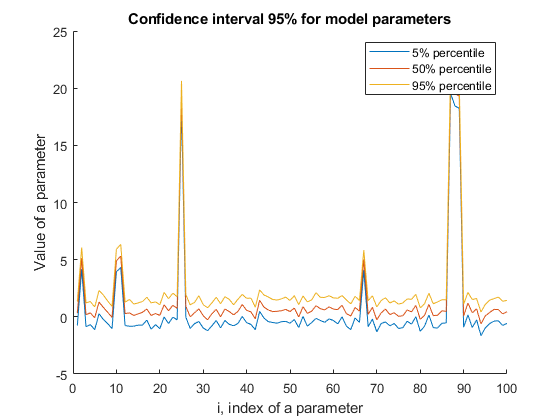


% perform the bootstraps
modelfit = zeros(numboots, length(data1));
params = zeros(numboots, size_of_regressors);


% Goot point to remember:
% In this case, regressors are x-values, what are used to estimate y
% values. data1 is y-values. Parameters of the model are unknown.

for boot=1:numboots
    
    % prepare data indices
    % rand(1,n) = [0:1](1x100)
    ix = ceil(n*rand(1,bunch_of_sample));
    
    % construct regressor matrix
    X = regressors1(ix,:);
    
    % edstimate parameters
    h = inv(X' * X) * X'*data1(ix);
   
    
    % record the parameters
    params(boot,:) = h;
end

% Calculate percentils for parameters
paramsP = prctile(params,[2.5 50 97.5],1);

% visualize
figure;
hold on;
xlabel('i, index of a parameter')
ylabel('Value of a parameter')
a = plot(paramsP(1,:));
b = plot(paramsP(2,:));
c = plot(paramsP(3,:));

legend([a b c], '5% percentile', '50% percentile', '95% percentile');
title('Confidence interval 95% for model parameters');

% in k-fold cross-validation, we divite the data into k parts, leave out

n = 100

% one of the parts, train on the remaining parts, and then test on the
% left-out park. This process is repeated for each part.

n = length(xdata)
k = 10;                  % how many parts to use
allix = randperm(n);    % all data indices, randomly ordered
numineach = ceil(n/k);  % at least one part must have this many data points

allix = reshape([allix NaN(1,k*numineach-n)],k,numineach);

% Perform K-Fold cross-validation
for p=1:k
    testix = allix(p,:)  ;       % indices to use for testing
    testix(isnan(testix)) = []; % remove Nans if necessary
    
    trainix = setdiff(1:n, testix);
    
    
    % Sample train and test samples
    x_train = xdata(trainix,:);
    x_test = xdata(testix,:);
    
    y_train = ydata(trainix,:);
    y_test = ydata(testix,:);
    
    % construct regressor matrix for linear dependency
    X_lin = [x_train' ones(length(x_train'),1)];
    
end

% Problem 3
% Our aim is ti check where there is a nonlinear or quadratic relationship
% between each subject. Then scatter plot to compare the accuracy of the
% linear model and the accuracy fo the quadratic model.

numfolds = 10;  % number of subsets to use in cross-validation


numsubjects = size(xdata,2);
numdatapoints = size(xdata,1);


% generate a random split of the data points into parts.
% allix is a 2D matrix of idices, with dimensions [parts] x [indices].
allix = randperm(numdatapoints);
numineach = ceil(numdatapoints/numfolds);
allix = reshape([allix NaN(1,numfolds*numineach-numdatapoints)],numfolds,numineach);


% Calcilate R2 function
computeR2 = @(model, data) 100 * (1 - sum((data-model).^2) / sum((data - mean(data)).^2));


R2_linear = zeros(1, numsubjects);
R2_quadratic = zeros(1, numsubjects);

% analyze each subject
for subject=1:numsubjects
    
    % perform k-fold cross validation
    
    prediction_linear = zeros(numdatapoints,1);
    prediction_quadratic = zeros(numdatapoints,1);
    
    for fold=1:numfolds
        
        testix = allix(fold, :);        % indices to use for testing
        testix(isnan(testix)) = [];
        trainix = setdiff(1:numdatapoints, testix);  % indices to use for training
        
        % set out data for linear model
        % prepare regressor matrices and data
        xtrain = [xdata(trainix, subject) ones(length(trainix),1)];
        ytrain = ydata(trainix, subject); 
        
        xtest = [xdata(testix, subject) ones(length(testix),1)];
        ytest = ydata(testix, subject); 
        
        % Train and test linear model
        h = inv(xtrain' * xtrain) * xtrain' * ytrain;
        prediction_linear(testix) = xtest*h;
        
        
        
        % set out data for quadratic model
        % prepare regressor matrices and data
        xtrain = [xdata(trainix, subject).^2 xdata(trainix, subject) ones(length(trainix),1)];
        ytrain = ydata(trainix, subject); 
        
        xtest = [xdata(testix, subject).^2 xdata(testix, subject) ones(length(testix),1)];
        ytest = ydata(testix, subject); 
        
        % Train and test linear model
        h = inv(xtrain' * xtrain) * xtrain' * ytrain;
        prediction_quadratic(testix) = xtest*h;
                
    end
    
    % quantify accuracy
    R2_linear(subject) = computeR2(prediction_linear, ydata(:, subject));
    R2_quadratic(subject) = computeR2(prediction_quadratic, ydata(:, subject));
    
    
end

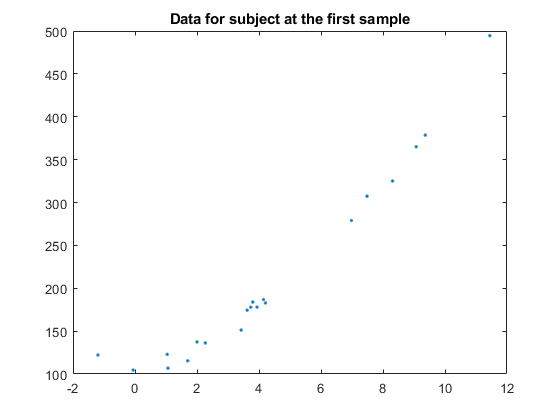

% visualize
figure;
title('Data for subjects at the first sample');
plot(xdata(1,:),ydata(1,:),'.');
title('Data for subject at the first sample');

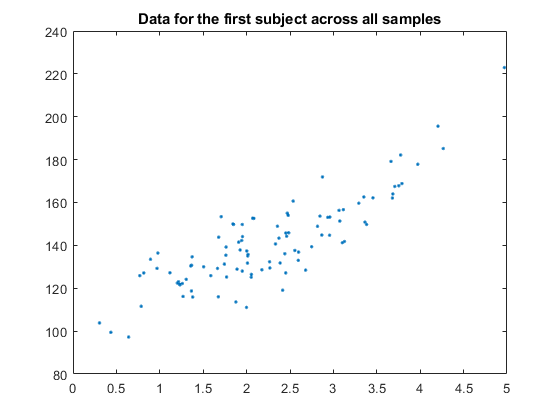


plot(xdata(:,1),ydata(:,1),'.');
title('Data for the first subject across all samples')

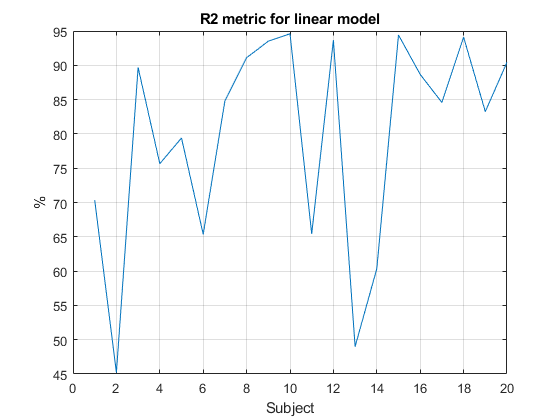



% visualize the R2 dependency for each subject
plot(R2_linear); grid;
title('R2 metric for linear model')
xlabel('Subject');
ylabel('%')

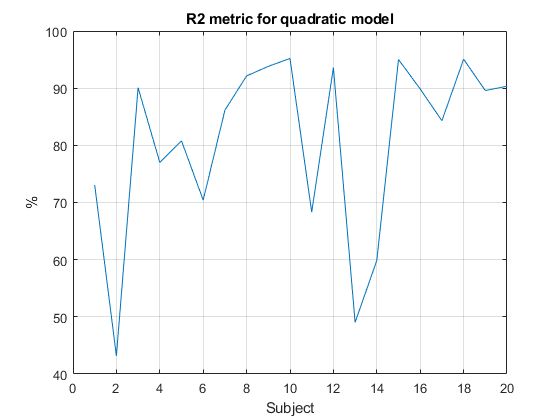


plot(R2_quadratic); grid;
title('R2 metric for quadratic model')
xlabel('Subject');
ylabel('%')

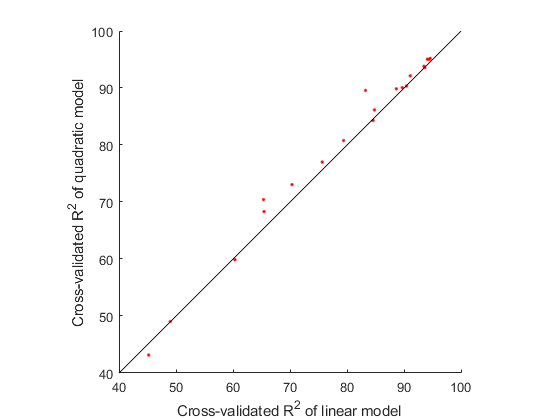

% visualize 
figure; 
hold on; 
scatter(R2_linear,R2_quadratic,'r.'); 
axis equal square; 
ax = axis; 
plot(ax(1:2),ax(1:2),'k-');
xlabel('Cross-validated R^2 of linear model'); 
ylabel('Cross-validated R^2 of quadratic model');


% Summary: taking a look at the last scatter plot, we can conclude that the
% model can be describe quite accurate using both linear and quadratic
% function